% --------- Double Pantograph (6-DOF) (ref. Stocco's thesis) ---------------

% This script calculates the direct kinematics problem of the 6DOF robot
% Inputs: 
%         Motor angles [q1 q2 q3 q4 q5 q6 q7] rad
%         Linkage lengths [l1 l2 l3 l4 l5 l6 l7 l8] cm -> currently internal

% Outputs: 4x4 Transformation from base to end-effector frame (XYZ, pose)
%          4x4 Transformations from base to all intermediate frames

% Figure 7.2 shows linkage lengths, active (motor) joints q

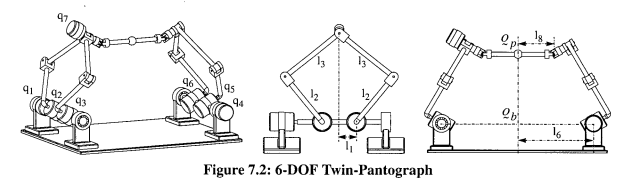

% Figure A.12 shows full 'serialized' version of 7.2 on left, half on right
% This INCLUDES pseudo-active joints in the serial chain - solved first
% Note that left is composed of the right side + segments thetas1-3 repeated

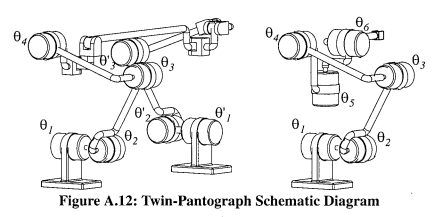

% Figure A.2 is the unfolded (all actuator angles = 0deg) schematic of the
% right 'serialized' kinematic chain on the right side of A.12

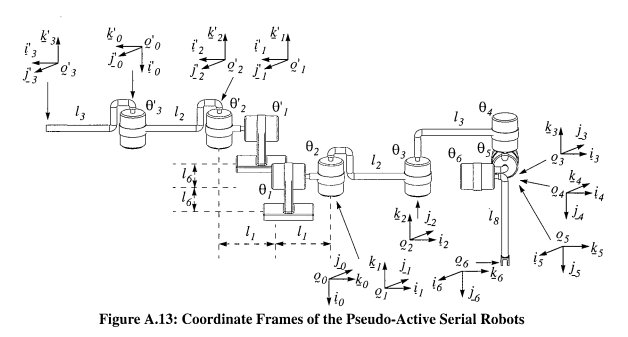

% First we compute the RHS chain above -- the right pantograph from base to e-e:

% Use the 5bar calculation function, with parameter side = 1 to designate the right pantograph chain
shoulderAngle_A = 0; % INPUT pitch of the RIGHT shoulder pantograph assembly chain
pantoAngleR_A = 47.45 * (2*pi)/360; % INPUT rotation of right pantograph motor
pantoAngleL_A = pi -  50.94 * (2*pi)/360; % INPUT of left pantograph motor

[Tb_0, Tb_1, Tb_2, Tb_3] = fiveBarForward(shoulderAngle_A, pantoAngleL_A, pantoAngleR_A, 1)

q4_2y = -0.6694

gamma3 = 0.8539

gamma3deg = 48.9489

gamma4 = 0.7056

gamma4deg = 40.4457

theta3 = 1.5822

theta3deg = 90.6966

Tb_0 =     1.0000         0         0   20.0000
         0    0.0000   -1.0000    2.0200
         0    1.0000    0.0000         0
         0         0         0    1.0000


T0_1 =     0.0000         0   -1.0000         0
         0    1.0000         0         0
    1.0000         0    0.0000         0
         0         0         0    1.0000


T1_2 =     0.6762   -0.7367         0   11.3742
    0.7367    0.6762         0   12.3911
         0         0    1.0000         0
         0         0         0    1.0000


T2_3 =    -0.0114   -0.9999         0   -0.1942
    0.9999   -0.0114         0   17.0989
         0         0    1.0000         0
         0         0         0    1.0000


Tb_3 =    -0.0000   -0.0000   -1.0000   20.0000
    0.7443    0.6678   -0.0000    3.3736
    0.6678   -0.7443    0.0000   23.8109
         0         0         0    1.0000


frame0XYZ =    20.0000    2.0200         0


frame1XYZ =    20.0000    2.0200         0


frame2XYZ =    20.0000   -9.3542   12.3911


endEffectorXYZ =    20.0000    3.3736   23.8109


Tb_0 =     1.0000         0         0   20.0000
         0    0.0000   -1.0000    2.0200
         0    1.0000    0.0000         0
         0         0         0    1.0000


Tb_1 =     0.0000         0   -1.0000   20.0000
   -1.0000    0.0000   -0.0000    2.0200
    0.0000    1.0000    0.0000         0
         0         0         0    1.0000


Tb_2 =     0.0000   -0.0000   -1.0000   20.0000
   -0.6762    0.7367   -0.0000   -9.3542
    0.7367    0.6762    0.0000   12.3911
         0         0         0    1.0000


Tb_3 =    -0.0000   -0.0000   -1.0000   20.0000
    0.7443    0.6678   -0.0000    3.3736
    0.6678   -0.7443    0.0000   23.8109
         0         0         0    1.0000



% Next we compute the LHS chain above -- the left pantograph from base to e-e
% According to Leo... only difference is that it is reflected to face the right panto, so rotate 180 about global z!

%{
eul = [pi 0 0]; 
C3_3p = eul2rotm(eul); 
c = [0;0;0]; % load the translation column vector
T3_3p = zeros(4,4); % initialize empty hom. 4x4 matrix
T3_3p(1:3,1:3) = C3_3p; % insertion of rot 3x3 into hom. 4x4
T3_3p(1:3, 4) = c; % insertion of translation vector into 4x4
T3_3p(4,4) = 1; % insertion of view factor into 4x4
T3_3p; % completed homogeneous 4x4 matrix
Tb_3p = Tb_3p * T3_3p
%}

% Suffice to say this didn't work for me, nor do I get how it would -- I need the endpoint of frame 3p to be
% translated -2*l6 units in the base frame's -x direction, so use my helper function:

% Use the 5bar calculation function, with parameter side = -1 to designate the left pantograph chain
shoulderAngle_A = 0; % INPUT pitch of the LEFT shoulder pantograph assembly chain
pantoAngleR_A = 47.45 * (2*pi)/360; % INPUT rotation of right pantograph motor
pantoAngleL_A = pi -  50.94 * (2*pi)/360; % INPUT of left pantograph motor

% Side Note - this means we can simulate mismatched sizes of pantographs!
% This might be good for milking a couple extra degrees of R, P, Y in rotation?
[Tb_0p, Tb_1p, Tb_2p, Tb_3p] = fiveBarForward(shoulderAngle_A, pantoAngleL_A, pantoAngleR_A, -1)

q4_2y = -0.6694

gamma3 = 0.8539

gamma3deg = 48.9489

gamma4 = 0.7056

gamma4deg = 40.4457

theta3 = 1.5822

theta3deg = 90.6966

Tb_0 =     1.0000         0         0  -20.0000
         0    0.0000   -1.0000    2.0200
         0    1.0000    0.0000         0
         0         0         0    1.0000


T0_1 =     0.0000         0   -1.0000         0
         0    1.0000         0         0
    1.0000         0    0.0000         0
         0         0         0    1.0000


T1_2 =     0.6762   -0.7367         0   11.3742
    0.7367    0.6762         0   12.3911
         0         0    1.0000         0
         0         0         0    1.0000


T2_3 =    -0.0114   -0.9999         0   -0.1942
    0.9999   -0.0114         0   17.0989
         0         0    1.0000         0
         0         0         0    1.0000


Tb_3 =    -0.0000   -0.0000   -1.0000  -20.0000
    0.7443    0.6678   -0.0000    3.3736
    0.6678   -0.7443    0.0000   23.8109
         0         0         0    1.0000


frame0XYZ =   -20.0000    2.0200         0


frame1XYZ =   -20.0000    2.0200         0


frame2XYZ =   -20.0000   -9.3542   12.3911


endEffectorXYZ =   -20.0000    3.3736   23.8109


Tb_0p =     1.0000         0         0  -20.0000
         0    0.0000   -1.0000    2.0200
         0    1.0000    0.0000         0
         0         0         0    1.0000


Tb_1p =     0.0000         0   -1.0000  -20.0000
   -1.0000    0.0000   -0.0000    2.0200
    0.0000    1.0000    0.0000         0
         0         0         0    1.0000


Tb_2p =     0.0000   -0.0000   -1.0000  -20.0000
   -0.6762    0.7367   -0.0000   -9.3542
    0.7367    0.6762    0.0000   12.3911
         0         0         0    1.0000


Tb_3p =    -0.0000   -0.0000   -1.0000  -20.0000
    0.7443    0.6678   -0.0000    3.3736
    0.6678   -0.7443    0.0000   23.8109
         0         0         0    1.0000



% Rotate frame at 3p (LEFT PANTO) to face the YZ plane, mirroring frame 3 (RIGHT PANTO)
eul = [pi 0 0]; 
C3_3p = eul2rotm(eul); 
c = [0;0;0]; % load the translation column vector
T3_3p = zeros(4,4); % initialize empty hom. 4x4 matrix
T3_3p(1:3,1:3) = C3_3p; % insertion of rot 3x3 into hom. 4x4
T3_3p(1:3, 4) = c; % insertion of translation vector into 4x4
T3_3p(4,4) = 1; % insertion of view factor into 4x4
T3_3p; % completed homogeneous 4x4 matrix
Tb_3p = Tb_3p * T3_3p

Tb_3p =     0.0000    0.0000   -1.0000  -20.0000
   -0.7443   -0.6678   -0.0000    3.3736
   -0.6678    0.7443    0.0000   23.8109
         0         0         0    1.0000




% The right pantograph e-e has a frame 3 sharing a coincident origin with subsequent frames 4,5
% Recall this is the side with a spherical joint (thetas 4,5,6) and only angle 4 is active

theta4 = pi/2; % End effector's encoded twist angle
theta5 = 0; % Pseudo-active U-joint axes
theta6 = 0; % 

% Transformation from frame 3 -> 4 (only rotation)
eul = [theta4 0 -pi/2]; 
C3_4 = eul2rotm(eul); 
c = [0;0;0]; % load the translation column vector
T3_4 = zeros(4,4); % initialize empty hom. 4x4 matrix
T3_4(1:3,1:3) = C3_4; % insertion of rot 3x3 into hom. 4x4
T3_4(1:3, 4) = c; % insertion of translation vector into 4x4
T3_4(4,4) = 1; % insertion of view factor into 4x4
T3_4; % completed homogeneous 4x4 matrix

Tb_4 = Tb_3 * T3_4 % Right hand chain, from base to e-e motor 

Tb_4 =    -0.0000    1.0000   -0.0000   20.0000
    0.6678    0.0000   -0.7443    3.3736
   -0.7443   -0.0000   -0.6678   23.8109
         0         0         0    1.0000



% Next is to solve the direction vector end effector axis:
frame3pXYZ = Tb_3p(1:3, 4).'

frame3pXYZ =   -20.0000    3.3736   23.8109


frame4XYZ = Tb_4(1:3, 4).'

frame4XYZ =    20.0000    3.3736   23.8109



j6 = ((frame3pXYZ - frame4XYZ)/norm(frame3pXYZ - frame4XYZ)).'; % unit vector connecting rod ends
% For extra clarity, this should be pointing from right panto tip >> left panto tip!

% Inverse kinematics of spherical (U) joint to solve for theta5
% !!!! There exist singularity issues and this is only reliable when the angle between j4 and j6 is < 90deg
j4 = Tb_4(1:3,2); % Extract the 2nd (y) column of the rot. matrix
checkOverZero = j4.'*j6 % Check that this is > 0

checkOverZero = -1

k4 = Tb_4(1:3,3);
i4 = Tb_4(1:3,1);
k5 = cross(j6,k4)/norm(cross(j6,k4))

k5 =          0
   -0.6678
    0.7443


theta5 = 2*atan(norm(k5-i4)/norm(k5 + i4)) * sign(k5.'*j4)

theta5 = -3.1416

theta5 = pi/8

theta5 = 0.3927


% Transformation from frame 4 -> 5 (only rotation)
eul = [theta5 pi/2 0]; 
C4_5 = eul2rotm(eul); 
c = [0;0;0]; % load the translation column vector
T4_5 = zeros(4,4); % initialize empty hom. 4x4 matrix
T4_5(1:3,1:3) = C4_5; % insertion of rot 3x3 into hom. 4x4
T4_5(1:3, 4) = c; % insertion of translation vector into 4x4
T4_5(4,4) = 1; % insertion of view factor into 4x4
T4_5; % completed homogeneous 4x4 matrix

% Inverse kinematics of spherical (U) joint to solve for theta6
Tb_5 = Tb_4 * T4_5;
j5 = Tb_4(1:3,2);
i5 = Tb_4(1:3,1);
theta6 = -2*atan(norm(j6-j5)/norm(j6 + j5)) * sign(j6.'*i5)

theta6 = -3.1416

theta6 = 0

theta6 = 0



% Transformation from frame 5 -> 6 (rotation, half length of e-e rod translation)
l8 = 20;
l8vec = [0; -l8; 0]; % in local coordinates of frame 5
eul = [theta6 0 0]; 
C5_6 = eul2rotm(eul); 
c = C5_6*l8vec;
T5_6 = zeros(4,4); % initialize empty hom. 4x4 matrix
T5_6(1:3,1:3) = C5_6; % insertion of rot 3x3 into hom. 4x4
T5_6(1:3, 4) = c; % insertion of translation vector into 4x4
T5_6(4,4) = 1; % insertion of view factor into 4x4
T5_6; % completed homogeneous 4x4 matrix

% Overall transformation:
Tb_6 = Tb_3 * T3_4 * T4_5 * T5_6

Tb_6 =     0.0000    0.9239    0.3827    1.5224
    0.7443   -0.2556    0.6170    8.4849
    0.6678    0.2848   -0.6877   18.1141
         0         0         0    1.0000




% Debug parameters (and for visualizer):
frame0XYZ = Tb_0(1:3, 4).'

frame0XYZ =    20.0000    2.0200         0



frame1XYZ = Tb_1(1:3, 4).'

frame1XYZ =    20.0000    2.0200         0



frame2XYZ = Tb_2(1:3, 4).'

frame2XYZ =    20.0000   -9.3542   12.3911



frame3XYZ = Tb_3(1:3, 4).'

frame3XYZ =    20.0000    3.3736   23.8109



frame4XYZ = Tb_4(1:3, 4).'

frame4XYZ =    20.0000    3.3736   23.8109



frame5XYZ = Tb_5(1:3, 4).'

frame5XYZ =    20.0000    3.3736   23.8109



frame6XYZ = Tb_6(1:3, 4).'

frame6XYZ =     1.5224    8.4849   18.1141



%End effector coordinates [x y z]

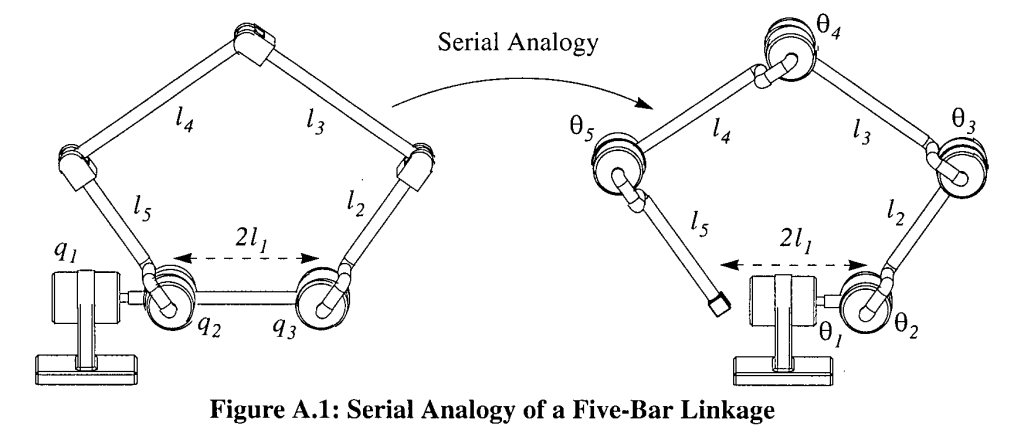

%{

 --------- Five-bar with shoulder (ref. Stocco's thesis) ---------------

 This function returns the 4x4 Transformation matrices for the final and
 intermediate frames of the 5-bar + shoulder pantograph linkage, from an
 origin base coordinate frame {0 0 0}.

 INPUTS: shoulder encoder angle (rad), left pantograph encoder angle, right
 pantograph encoder angle
    
 OUTPUTS: Four 4x4 Transformation matrices for base>frame_n (n = 0,1,2,3)
          Where 3 is the end effector
%}

% NOTE: for utility of this model we only need to translate base frame to
% the end effector @ theta4, we don't care about the left side motor/elbow

function [Tb_0, Tb_1, Tb_2, Tb_3] = fiveBarForward(shoulderAngle, pantoAngleL, pantoAngleR, side)

% Active (Encoded Motor) joint angles in rad*
theta1 = shoulderAngle; % INPUT pitch of the shoulder
theta2 = pantoAngleR; % INPUT rotation of right pantograph motor
q2 = pantoAngleL;


% Pseudo-Active joint angles in rad*
theta3 = 0;
theta4 = 0;
theta5 = 0;

% Bar lengths in cm*
l1 = 4.04/2; % Half of distance between panto motors

l2 = 16.820; % Motor to elbow linkage length
l5 = 16.820;

l3 = 17.10; % Elbow to tip linkage length
l4 = 17.09;

l6 = 20; % Half of distance between shoulder motors

% all linkage lengths in the x-dir of respective parent frames...
l1vec = [l1;0;0]; % Half of distance between panto motors

l2vec = [l2;0;0]; % Motor to elbow linkage length
l5vec = [l5;0;0];

l3vec = [l3;0;0]; % Elbow to tip linkage length
l4vec = [l4;0;0];

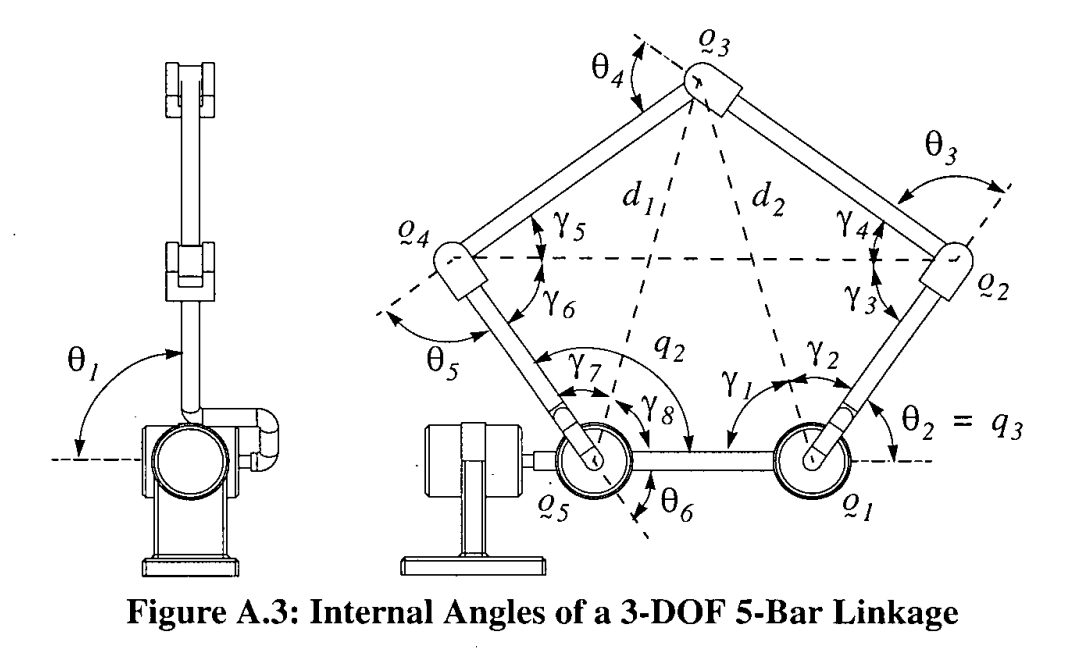

% 2D Inverse Kinematics to solve pseudo joint angle theta3 - [x0, y0 at Q1]
% Again, we do not care about anything past this, our end effector is Q3

q1_2x = l2*cos(theta2);
q1_2y = l2*sin(theta2);
q1_2 = [q1_2x; q1_2y];

% q4_2 is the vector drawn from q2 > q4 drawn above
q4_2x = q1_2x + 2*l1-l5*cos(q2);
q4_2y = q1_2y - l5*sin(q2)
q4_2 = [q4_2x; q4_2y];

% Leo's math here gets quarantined:
% gamma3 = 2*atan2(norm(q4_2 - q1_2), norm(q4_2 + q1_2)) * sign(theta2 - atan2(q4_2y,q4_2x))

% Compute the angle of vector q4_2
angle_q4_2 = atan2(q4_2y, q4_2x);

% Calculate gamma3 as the difference between theta2 and angle_q4_2 relative
% to base x-axis
gamma3 = theta2 - angle_q4_2
gamma3deg = gamma3 * 360 /6.28

gamma4 = pi - 2*atan(sqrt(((norm(q4_2) + l3)^2 - l4^2) / (l4^2 - (norm(q4_2) - l3)^2)))
gamma4deg = gamma4 * 360 /6.28

theta3 = pi - gamma3 - gamma4 % was playing with the error + (5* 2*pi/360)
theta3deg = theta3 * 360 /6.28



% test fix case: theta3 = 90.64 * 2 * pi / 360 % error of -4.2154deg



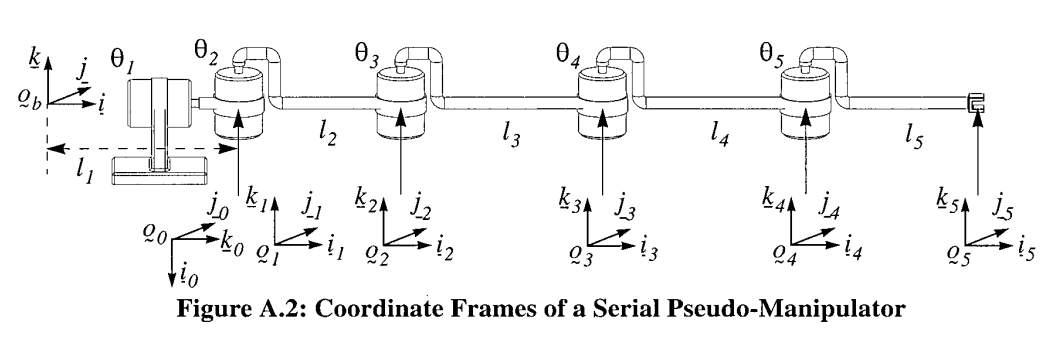

% Matrix Transformations
% I alter Leo Stocco's math here to reorient our robot to face upwards in 'c' below:
% Left side applies -1 * l6 -> this models the left pantograph; right side applies +1 * l6

eul = [0 0 pi/2]; % Z-Y-X, or k-j-i !!!
Cb_0 = eul2rotm(eul);
c = [side*l6; l1; 0]; % x offset is half panto motor distance, z offset is half shoulder dist
Tb_0 = zeros(4,4); % initialize empty hom. 4x4 matrix
Tb_0(1:3,1:3) = Cb_0; % insertion of rot 3x3 into hom. 4x4
Tb_0(1:3, 4) = c; % insertion of translation vector into 4x4
Tb_0(4,4) = 1; % insertion of view factor into 4x4
Tb_0 % completed homogeneous 4x4 matrix

eul = [theta1 -pi/2 0]; 
C0_1 = eul2rotm(eul);
c = [0; 0; 0]; 
T0_1 = zeros(4,4); % initialize empty hom. 4x4 matrix
T0_1(1:3,1:3) = C0_1; % insertion of rot 3x3 into hom. 4x4
T0_1(1:3, 4) = c; % insertion of translation vector into 4x4
T0_1(4,4) = 1; % insertion of view factor into 4x4
T0_1 % completed homogeneous 4x4 matrix

eul = [theta2 0 0]; 
C1_2 = eul2rotm(eul); 
c = C1_2*l2vec; 
T1_2 = zeros(4,4); % initialize empty hom. 4x4 matrix
T1_2(1:3,1:3) = C1_2; % insertion of rot 3x3 into hom. 4x4
T1_2(1:3, 4) = c; % insertion of translation vector into 4x4
T1_2(4,4) = 1; % insertion of view factor into 4x4
T1_2 % completed homogeneous 4x4 matrix

eul = [theta3 0 0]; 
C2_3 = eul2rotm(eul); 
c = C2_3*l3vec; 
T2_3 = zeros(4,4); % initialize empty hom. 4x4 matrix
T2_3(1:3,1:3) = C2_3; % insertion of rot 3x3 into hom. 4x4
T2_3(1:3, 4) = c; % insertion of translation vector into 4x4
T2_3(4,4) = 1; % insertion of view factor into 4x4
T2_3 % completed homogeneous 4x4 matrix

% Overall Transformation:
Tb_3 = Tb_0 * T0_1 * T1_2 * T2_3


% Debug parameters:
frame0XYZ = Tb_0(1:3, 4).'

Tb_1 = Tb_0 * T0_1;
frame1XYZ = Tb_1(1:3, 4).'

Tb_2 = Tb_0 * T0_1 * T1_2;
frame2XYZ = Tb_2(1:3, 4).'

%End effector coordinates [x y z]
endEffectorXYZ = Tb_3(1:3, 4).'

end
